%% Remittance Model Analysis for Problem Set 2
% This script runs the remittance model with synthetic data and produces plots
% needed to answer the required questions

%% Clear workspace and set path
clear all;
close all;
clc;

fprintf('=== Vietnamese Household Life Cycle Model with Remittances ===\n');

=== Vietnamese Household Life Cycle Model with Remittances ===



%% Setup models with synthetic data
fprintf('Setting up baseline and remittance models with synthetic data...\n');

Setting up baseline and remittance models with synthetic data...



% Baseline model setup with synthetic Gt
par_base = model.setup();
par_base.Gt = model.create_synthetic_income_profile(par_base.T, par_base.tr, par_base.kappa);
par_base = model.gen_grids(par_base);

% Remittance model setup with synthetic Gt
par_remit = model_remittance.setup();
par_remit.Gt = model_remittance.create_synthetic_income_profile(par_remit.T, par_remit.tr, par_remit.kappa);
par_remit = model_remittance.gen_grids(par_remit);

%% Step 1: Solve and simulate both models with default parameters (β=0.94, γ=2.00)
fprintf('Solving and simulating models with default parameters (β=0.94, γ=2.00)...\n');

Solving and simulating models with default parameters (β=0.94, γ=2.00)...



% Solve models
sol_base = solve.lc(par_base);

------------Solving the Vietnamese Household Life Cycle Model------------

Solving for age: 74
Solving for age: 69
Solving for age: 59
Solving for age: 49
Solving for age: 39
Solving for age: 29
Solving for age: 19
Solving for age: 9
Solving for age: 0
------------Life Cycle Problem Solved------------


sol_remit = solve_remittance.lc(par_remit);

------------Solving the Vietnamese Household Life Cycle Model with Remittances------------

Solving for age: 74
Solving for age: 69
Solving for age: 59
Solving for age: 49
Solving for age: 39
Solving for age: 29
Solving for age: 19
Solving for age: 9
Solving for age: 0
------------Life Cycle Problem with Remittances Solved------------



% Simulate models
sim_base = simulate.lc(par_base, sol_base);
sim_remit = simulate_remittance.lc(par_remit, sol_remit);

%% Step 2: Plot life cycle profiles for comparison
fprintf('Plotting life cycle profiles for comparison...\n');

Plotting life cycle profiles for comparison...



% Plot consumption comparison
figure('Name', 'Consumption Profile Comparison');
plot(sim_base.ages, sim_base.c_profile, 'b-', 'LineWidth', 2);
hold on;
plot(sim_remit.ages, sim_remit.c_profile, 'r--', 'LineWidth', 2);
title('Life Cycle Profile of Consumption (β=0.94, γ=2.00)');
xlabel('Age');
ylabel('Consumption');
legend('Baseline', 'With Remittances', 'Location', 'best');
grid on;

% Plot wealth comparison
figure('Name', 'Wealth Profile Comparison');
plot(sim_base.ages, sim_base.a_profile, 'b-', 'LineWidth', 2);
hold on;
plot(sim_remit.ages, sim_remit.a_profile, 'r--', 'LineWidth', 2);
title('Life Cycle Profile of Wealth (β=0.94, γ=2.00)');
xlabel('Age');
ylabel('Wealth');
legend('Baseline', 'With Remittances', 'Location', 'best');
grid on;

% Plot remittance profile
figure('Name', 'Remittance Profile');
subplot(2,1,1);
bar(sim_remit.ages, sim_remit.r_profile);
title('Average Remittance Amount by Age');
xlabel('Age');
ylabel('Amount');
grid on;

subplot(2,1,2);
bar(sim_remit.ages, sim_remit.remit_freq);
title('Probability of Receiving Remittances by Age');
xlabel('Age');
ylabel('Probability');
grid on;

%% Step 3: Parameter variations - Solve for different β and γ combinations
fprintf('Solving and simulating for different parameter combinations...\n');

Solving and simulating for different parameter combinations...



% Solve baseline model for different parameters
sol_collection_base = solve.lc_param_variations(par_base);

Solving model for 16 parameter combinations...
Solving combination 1/16: beta = 0.90, gamma = 2.00
------------Solving the Vietnamese Household Life Cycle Model------------

Solving for age: 74
Solving for age: 69
Solving for age: 59
Solving for age: 49
Solving for age: 39
Solving for age: 29
Solving for age: 19
Solving for age: 9
Solving for age: 0
------------Life Cycle Problem Solved------------
Solving combination 2/16: beta = 0.90, gamma = 3.00
------------Solving the Vietnamese Household Life Cycle Model------------

Solving for age: 74
Solving for age: 69
Solving for age: 59
Solving for age: 49
Solving for age: 39
Solving for age: 29
Solving for age: 19
Solving for age: 9
Solving for age: 0
------------Life Cycle Problem Solved------------
Solving combination 3/16: beta = 0.90, gamma = 4.00
------------Solving the Vietnamese Household Life Cycle Model------------

Solving for age: 74
Solving for age: 69
Solving for age: 59
Solving for age: 49
Solving for age: 39
Solving for age:

param_results_base = simulate.param_variations(par_base, sol_collection_base);

Simulating for different beta values with gamma = 2.00...
  Simulating for beta = 0.90
  Simulating for beta = 0.92
  Simulating for beta = 0.94
  Simulating for beta = 0.96
Simulating for different gamma values with beta = 0.96...
  Simulating for gamma = 2.00
  Simulating for gamma = 3.00
  Simulating for gamma = 4.00
  Simulating for gamma = 5.00
Creating data for average wealth heat map...



% Solve remittance model for different parameters
sol_collection_remit = solve_remittance.lc_param_variations(par_remit);

Solving model with remittances for 16 parameter combinations...
Solving combination 1/16: beta = 0.90, gamma = 2.00
------------Solving the Vietnamese Household Life Cycle Model with Remittances------------

Solving for age: 74
Solving for age: 69
Solving for age: 59
Solving for age: 49
Solving for age: 39
Solving for age: 29
Solving for age: 19
Solving for age: 9
Solving for age: 0
------------Life Cycle Problem with Remittances Solved------------
Solving combination 2/16: beta = 0.90, gamma = 3.00
------------Solving the Vietnamese Household Life Cycle Model with Remittances------------

Solving for age: 74
Solving for age: 69
Solving for age: 59
Solving for age: 49
Solving for age: 39
Solving for age: 29
Solving for age: 19
Solving for age: 9
Solving for age: 0
------------Life Cycle Problem with Remittances Solved------------
Solving combination 3/16: beta = 0.90, gamma = 4.00
------------Solving the Vietnamese Household Life Cycle Model with Remittances------------

Solving for ag

param_results_remit = simulate_remittance.param_variations(par_remit, sol_collection_remit);

Simulating for different beta values with gamma = 2.00...
  Simulating for beta = 0.90
  Simulating for beta = 0.92
  Simulating for beta = 0.94
  Simulating for beta = 0.96
Simulating for different gamma values with beta = 0.96...
  Simulating for gamma = 2.00
  Simulating for gamma = 3.00
  Simulating for gamma = 4.00
  Simulating for gamma = 5.00
Creating data for average wealth heat map...



%% Step 4: Plot heat maps of average wealth
fprintf('Plotting heat maps for average wealth...\n');

Plotting heat maps for average wealth...



% Plot heat map for baseline model
figure('Name', 'Average Wealth - Baseline Model');
my_graph.plot_wealth_heatmap(param_results_base.beta_values, param_results_base.gamma_values, param_results_base.avg_wealth);

% Plot heat map for remittance model
figure('Name', 'Average Wealth - Remittance Model');
graph_remittance.plot_wealth_heatmap(param_results_remit.beta_values, param_results_remit.gamma_values, param_results_remit.avg_wealth);

% Plot heat map of percentage difference
figure('Name', 'Wealth Increase with Remittances (%)');
pct_diff = 100 * (param_results_remit.avg_wealth ./ param_results_base.avg_wealth - 1);
imagesc(param_results_remit.gamma_values, param_results_remit.beta_values, pct_diff);
colorbar;
title('Percent Increase in Average Wealth with Remittances (%)');
xlabel('\gamma (Risk Aversion)');
ylabel('\beta (Discount Factor)');
set(gca, 'YDir', 'normal');
xticks(1:length(param_results_remit.gamma_values));
yticks(1:length(param_results_remit.beta_values));
xticklabels(arrayfun(@(x) sprintf('%.2f', x), param_results_remit.gamma_values, 'UniformOutput', false));
yticklabels(arrayfun(@(x) sprintf('%.2f', x), param_results_remit.beta_values, 'UniformOutput', false));
colormap('jet');

%% Step 5: Sensitivity analysis of remittance-specific parameters
fprintf('Analyzing sensitivity to remittance parameters...\n');

Analyzing sensitivity to remittance parameters...



sensitivity_results = solve_remittance.remittance_sensitivity(par_remit, sol_remit);

Analyzing sensitivity to remittance persistence (eta)...
  Simulating for eta = 0.50
------------Solving the Vietnamese Household Life Cycle Model with Remittances------------

Solving for age: 74
Solving for age: 69
Solving for age: 59
Solving for age: 49
Solving for age: 39
Solving for age: 29
Solving for age: 19
Solving for age: 9
Solving for age: 0
------------Life Cycle Problem with Remittances Solved------------
  Simulating for eta = 0.70
------------Solving the Vietnamese Household Life Cycle Model with Remittances------------

Solving for age: 74
Solving for age: 69
Solving for age: 59
Solving for age: 49
Solving for age: 39
Solving for age: 29
Solving for age: 19
Solving for age: 9
Solving for age: 0
------------Life Cycle Problem with Remittances Solved------------
  Simulating for eta = 0.90
------------Solving the Vietnamese Household Life Cycle Model with Remittances------------

Solving for age: 74
Solving for age: 69
Solving for age: 59
Solving for age: 49
Solving for a

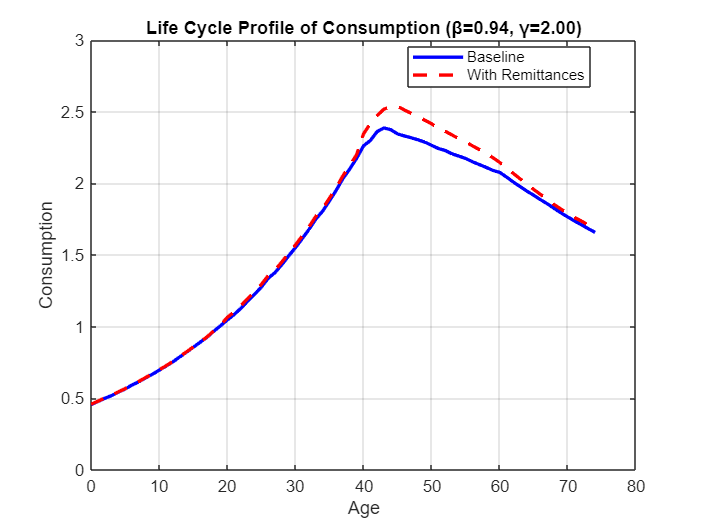

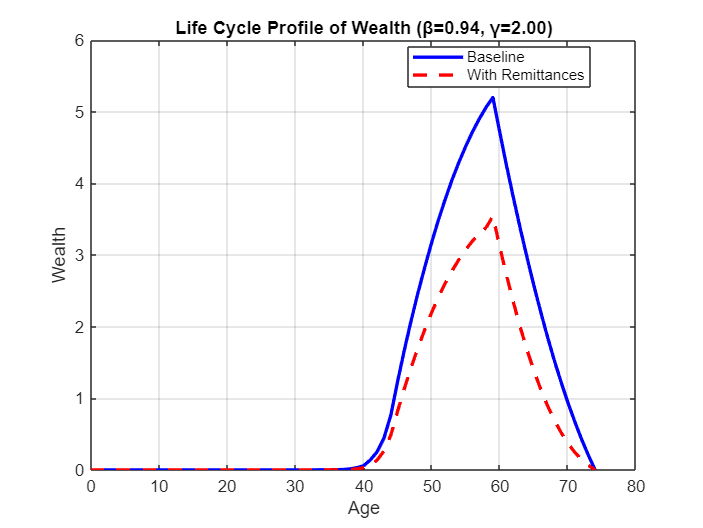

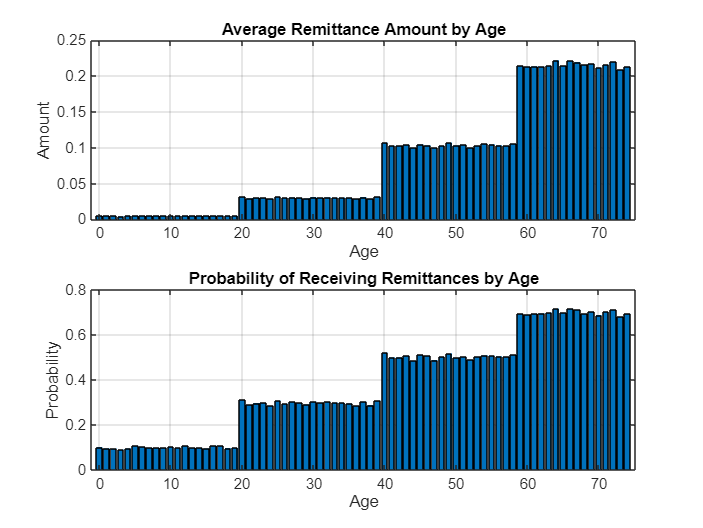

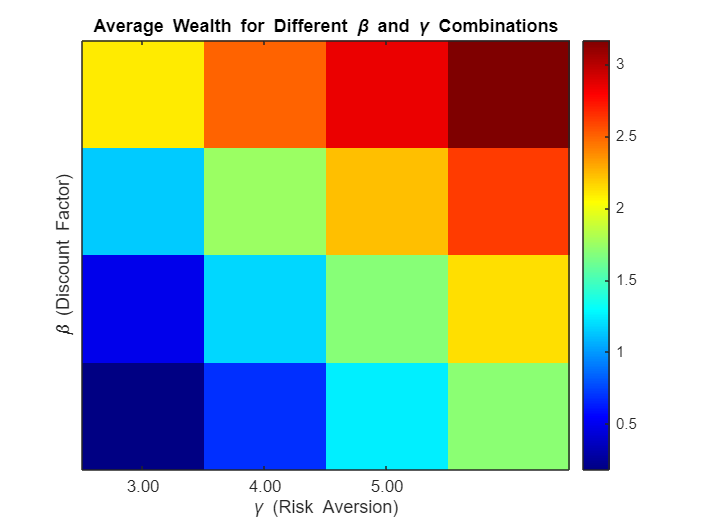

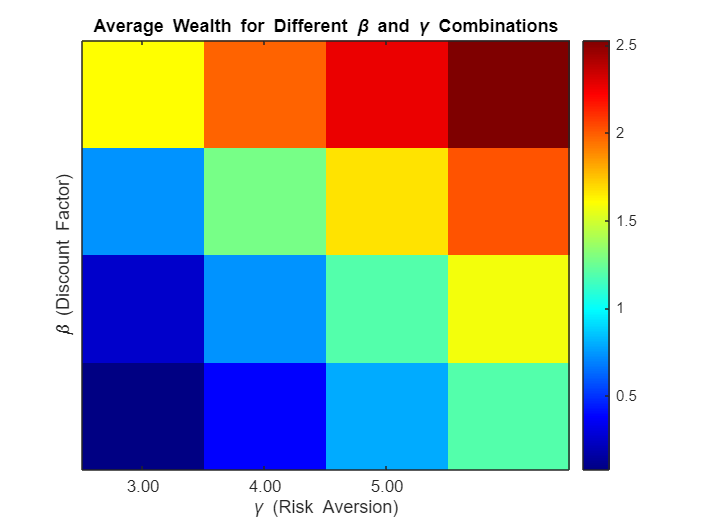

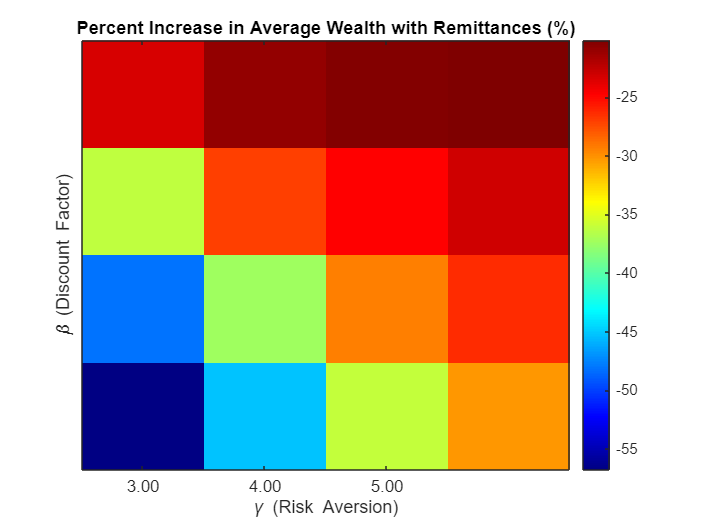

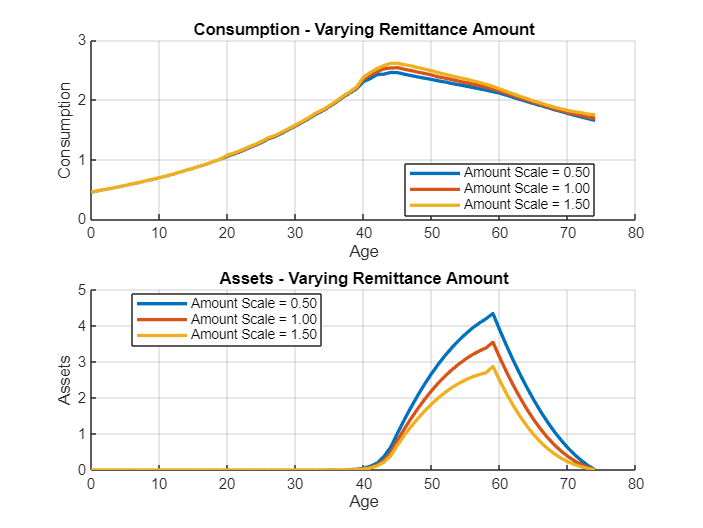

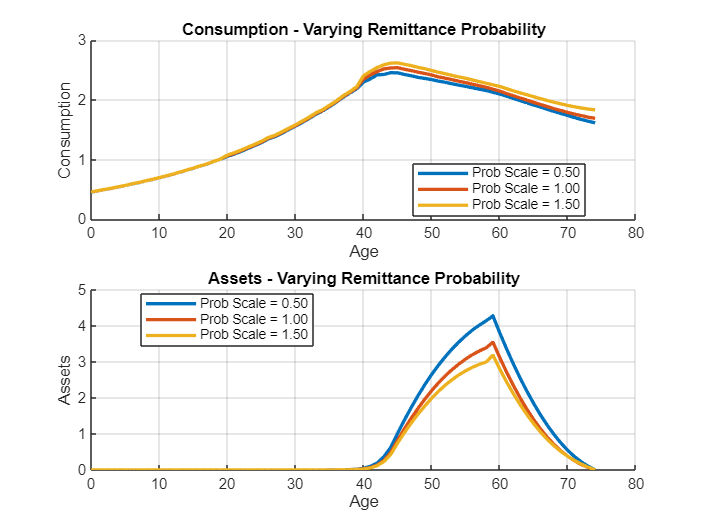

graph_remittance.plot_remittance_sensitivity(sim_remit.ages, sensitivity_results);


%% Step 6: Calculate and display summary statistics
fprintf('Calculating summary statistics...\n');

Calculating summary statistics...


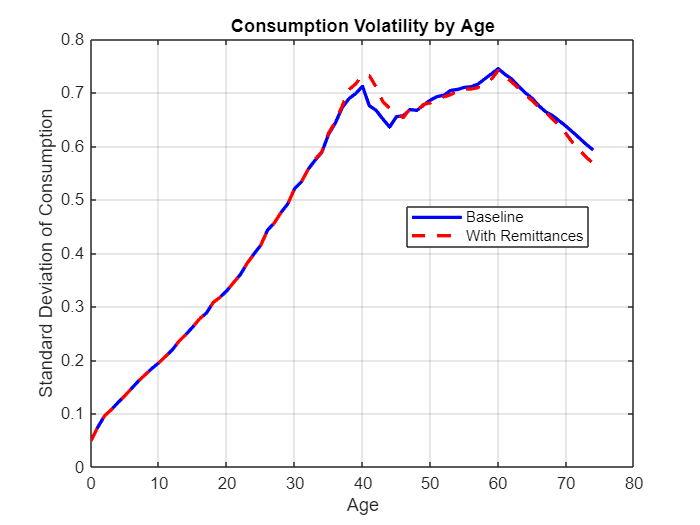


% Calculate key statistics
stats = struct();

% Consumption stats
stats.c_mean_base = mean(sim_base.c_profile);
stats.c_mean_remit = mean(sim_remit.c_profile);
stats.c_var_base = var(sim_base.c_profile);
stats.c_var_remit = var(sim_remit.c_profile);

% Wealth stats
stats.a_mean_base = mean(sim_base.a_profile);
stats.a_mean_remit = mean(sim_remit.a_profile);

% Ratios
stats.c_y_ratio_base = mean(sim_base.c_profile) / mean(sim_base.y_profile);
stats.c_y_ratio_remit = mean(sim_remit.c_profile) / mean(sim_remit.y_profile + sim_remit.r_profile);
stats.a_y_ratio_base = mean(sim_base.a_profile) / mean(sim_base.y_profile);
stats.a_y_ratio_remit = mean(sim_remit.a_profile) / mean(sim_remit.y_profile + sim_remit.r_profile);

% Consumption volatility by age
c_var_by_age_base = zeros(size(sim_base.ages));
c_var_by_age_remit = zeros(size(sim_remit.ages));

for age = 1:length(sim_base.ages)
    c_var_by_age_base(age) = var(sim_base.csim(:, age));
    c_var_by_age_remit(age) = var(sim_remit.csim(:, age));
end

% Plot consumption variance by age
figure('Name', 'Consumption Variance by Age');
plot(sim_base.ages, sqrt(c_var_by_age_base), 'b-', 'LineWidth', 2);
hold on;
plot(sim_remit.ages, sqrt(c_var_by_age_remit), 'r--', 'LineWidth', 2);
title('Consumption Volatility by Age');
xlabel('Age');
ylabel('Standard Deviation of Consumption');
legend('Baseline', 'With Remittances', 'Location', 'best');
grid on;


% Display summary statistics
fprintf('\nSummary Statistics:\n');


Summary Statistics:


fprintf('------------------\n');

------------------


fprintf('Mean Consumption (Base): %.4f\n', stats.c_mean_base);

Mean Consumption (Base): 1.5741


fprintf('Mean Consumption (Remit): %.4f\n', stats.c_mean_remit);

Mean Consumption (Remit): 1.6231


fprintf('Change in Mean Consumption: %.2f%%\n', 100*(stats.c_mean_remit/stats.c_mean_base-1));

Change in Mean Consumption: 3.11%


fprintf('Consumption/Income Ratio (Base): %.4f\n', stats.c_y_ratio_base);

Consumption/Income Ratio (Base): 1.0124


fprintf('Consumption/Income Ratio (Remit): %.4f\n', stats.c_y_ratio_remit);

Consumption/Income Ratio (Remit): 0.9918


fprintf('Mean Wealth (Base): %.4f\n', stats.a_mean_base);

Mean Wealth (Base): 1.1460


fprintf('Mean Wealth (Remit): %.4f\n', stats.a_mean_remit);

Mean Wealth (Remit): 0.7305


fprintf('Change in Mean Wealth: %.2f%%\n', 100*(stats.a_mean_remit/stats.a_mean_base-1));

Change in Mean Wealth: -36.26%


fprintf('Wealth/Income Ratio (Base): %.4f\n', stats.a_y_ratio_base);

Wealth/Income Ratio (Base): 0.7371


fprintf('Wealth/Income Ratio (Remit): %.4f\n', stats.a_y_ratio_remit);

Wealth/Income Ratio (Remit): 0.4464


fprintf('Consumption Volatility (Base): %.4f\n', sqrt(stats.c_var_base));

Consumption Volatility (Base): 0.6268


fprintf('Consumption Volatility (Remit): %.4f\n', sqrt(stats.c_var_remit));

Consumption Volatility (Remit): 0.6706


fprintf('Consumption Smoothing Improvement: %.2f%%\n', 100*(1-sqrt(stats.c_var_remit)/sqrt(stats.c_var_base)));

Consumption Smoothing Improvement: -6.99%



fprintf('\nAnalysis complete. All necessary plots and statistics have been generated.\n');


Analysis complete. All necessary plots and statistics have been generated.
